# Lab 9 Radio Havana

### ### Insert Name ###

## Item 0: Load Workspace 

close all
clear

load short_wave.mat

N = length(x_IQ);


## Item 1: Plot Spectrum of Down-converted Signal

X_IQ = abs(fftshift(fft(x_IQ)))

X_IQ = 1.0e+05 *

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000



index = find(X_IQ < 0)


index =

  1×0 empty double row vector



X_IQ(index)


ans =

  1×0 empty double row vector



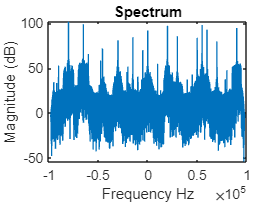


freq_x = [-(N-1)/2:(N-1)/2]*Fs/N; % DFT frequencies in continous time

plot(freq_x, 20*log10(X_IQ))
xlabel('Frequency Hz')  % <-- Axis label
ylabel('Magnitude (dB)') % <-- Axis label
title('Spectrum') % <-- graph title

## Item 3: Find DFT indices for the Carrier Frequency and Tolerance

% find exact carrier frequency
fc = -65000; % Hz
% -30000 - never gonna give you up
% -80000 - vipers
% 70000 - nursery
%-65000 - service time
tol = 1000; % Hz

% Complete the following lines of code and uncomment to run

hzpersam = 196078/4194303;

% Calculate ind_c and ind_tol in terms of fc and tol 
    % Hint: Make sure you understand how ind_c and ind_tol are used in
    % getPeak.m
ind_c = 2097152 + round(fc/Fs * length(X_IQ))  % <-- Index corresponding to fc (integer)

ind_c = 706737

ind_tol = round(tol/Fs * length(X_IQ));  % <-- Index corresponding to tol (integer)

ind_i = getPeak(X_IQ, ind_c, ind_tol);  % Make sure you have this function in the workspace
f_i = freq_x(ind_i);  %frequency corresponding to peak index



## Item 4: Demodulate Radio Havana

% Demodulate message to account for inexact carrier frequency

% Complete the following line of code and uncomment to run
t = 0:N-1

t =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49


s = exp(-j*2*pi*f_i*t/Fs); % <--- complex sinusoid corresponding to exact carrier
x_b = real(x_IQ.*s);

% Complete the following line of code and uncomment to run
a = filter(h,1,x_b);  % <--- apply lowpass filter

% Play demodulated signal
soundsc(a,Fs)

imag(s(20000))

ans = -0.2130


% Plot Demodulated Signal Spectrum

% Complete the following lines of code and uncomment to run
figure
plot(freq_x, 20*log10(fftshift(fft(a))));

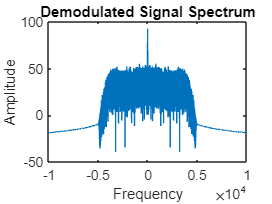

xlabel("Frequency")
ylabel("Amplitude")
title('Demodulated Signal Spectrum')
xlim([-10000,10000])

## Item 5: Plot Frequency Response of Final Low Pass Filter

**Note**: The following plot will be used for the corresponding Lab Assignment

[H,freq_h] = freqz(h,1,8192,Fs);

H(3997)

ans = -4.4514e-05 - 3.1812e-05i

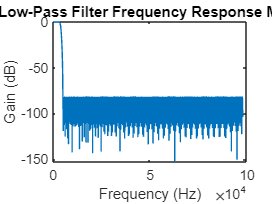


figure
plot(freq_h,20*log10(abs(H)))
xlabel('Frequency (Hz)')
ylabel('Gain (dB)')
title('Final Low-Pass Filter Frequency Response Magnitude')